PWM波形数组:


[


0

, 

0

, 

0

, 

0

, 

0

, 

0

, 

0

, 

1

, 

1

, 

1

, 

1

, 

1

, 

1

, 

1

, 

2

, 

2

, 

2

, 

2

, 

2

, 

2

, 

3

, 

3

, 

3

, 

4

, 

4

, 

4

, 

4

, 

5

, 

5

, 

6

, 

6

, 

7

, 

7

, 

8

, 

8

, 

9

, 

10

, 

10

, 

11

, 

12

, 

13

, 

14

, 

15

, 

16

, 

17

, 

18

, 

19

, 

21

, 

22

, 

24

, 

25

, 

27

, 

29

, 

31

, 

33

, 

36

, 

38

, 

41

, 

44

, 

47

, 

50

, 

53

, 

57

, 

61

, 

65

, 

70

, 

74

, 

79

, 

85

, 

91

, 

97

, 

104

, 

111

, 

118

, 

126

, 

135

, 

144

, 

154

, 

164

, 

176

, 

188

, 

200

, 

214

, 

229

, 

244

, 

261

, 

278

, 

297

, 

317

, 

339

, 

362

, 

387

, 

413

, 

441

, 

471

, 

503

, 

537

, 

573

, 

612

, 

654

, 

698

, 

745

, 

796

, 

850

, 

907

, 

969

, 

1034

, 

1104

, 

1179

, 

1259

, 

1344

, 

1435

, 

1533

, 

1636

, 

1747

, 

1866

, 

1992

, 

2127

, 

2271

, 

2425

, 

2589

, 

2764

, 

2951

, 

3151

, 

3364

, 

3592

, 

3835

, 

4095

, 

4095

, 

3835

, 

3592

, 

3364

, 

3151

, 

2951

, 

2764

, 

2589

, 

2425

, 

2271

, 

2127

, 

1992

, 

1866

, 

1747

, 

1636

, 

1533

, 

1435

, 

1344

, 

1259

, 

1179

, 

1104

, 

1034

, 

969

, 

907

, 

850

, 

796

, 

745

, 

698

, 

654

, 

612

, 

573

, 

537

, 

503

, 

471

, 

441

, 

413

, 

387

, 

362

, 

339

, 

317

, 

297

, 

278

, 

261

, 

244

, 

229

, 

214

, 

200

, 

188

, 

176

, 

164

, 

154

, 

144

, 

135

, 

126

, 

118

, 

111

, 

104

, 

97

, 

91

, 

85

, 

79

, 

74

, 

70

, 

65

, 

61

, 

57

, 

53

, 

50

, 

47

, 

44

, 

41

, 

38

, 

36

, 

33

, 

31

, 

29

, 

27

, 

25

, 

24

, 

22

, 

21

, 

19

, 

18

, 

17

, 

16

, 

15

, 

14

, 

13

, 

12

, 

11

, 

10

, 

10

, 

9

, 

8

, 

8

, 

7

, 

7

, 

6

, 

6

, 

5

, 

5

, 

4

, 

4

, 

4

, 

4

, 

3

, 

3

, 

3

, 

2

, 

2

, 

2

, 

2

, 

2

, 

2

, 

1

, 

1

, 

1

, 

1

, 

1

, 

1

, 

1

, 

0

, 

0

, 

0

, 

0

, 

0

, 

0

, 

0

]


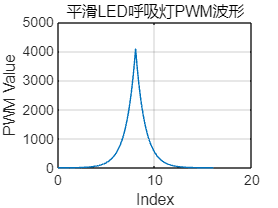

% 极致平滑呼吸灯PWM生成器（完整数组输出版）
POINT_NUM = 256;        % 推荐256点（FFT友好）
MAX_POWER = 8;          % 控制曲线陡峭度
GAMMA = 2.3;            % 人眼响应参数（2.2-2.5）

%% ===== 核心PWM数组生成 =====
% 生成Gamma校正曲线（上升阶段）
x_rise = linspace(0, 1, POINT_NUM/2);
pwm_rise = round(255 * (x_rise.^GAMMA));

% 生成下降阶段（对称Gamma曲线）
x_fall = linspace(1, 0, POINT_NUM/2);
pwm_fall = round(255 * (x_fall.^GAMMA));

% 合并完整波形
pwm_array = [pwm_rise(1:end-1), pwm_fall];

% 低区平滑强化（前20点特殊处理）
pwm_array(1:20) = round(interp1([1,20], [0,pwm_array(21)], 1:20));

% 高斯滤波去台阶
pwm_array = smoothdata(pwm_array, 'gaussian', 15);

%% ===== 完整数组输出 =====
% 控制台打印（前20点示例）
disp('PWM数组前20点:');
fprintf('%d ', pwm_array(1:20));
fprintf('\n...\n');

% 生成Arduino头文件
fid = fopen('pwm_table.h','w');
fprintf(fid, 'const uint8_t pwmTable[%d] PROGMEM = {\n', POINT_NUM);
for i = 1:POINT_NUM
    fprintf(fid, '%3d', pwm_array(i));
    if i ~= POINT_NUM, fprintf(fid, ','); end
    if mod(i,16) == 0, fprintf(fid, '\n'); end
end
fprintf(fid, '};\n');
fclose(fid);

%% ===== 可视化验证 =====
figure('Position',[100,100,900,400]);

% 时域波形
subplot(1,2,1);
plot(pwm_array, '-b', 'LineWidth', 1.5);
hold on;
stem(pwm_array, 'filled', 'MarkerSize',4);
title('PWM时域波形');
xlabel('时间点'); ylabel('PWM值');
grid on;

% 亮度感知曲线
subplot(1,2,2);
perceived = (pwm_array/255).^(1/2.2);  % 反Gamma变换
plot(perceived, '-r', 'LineWidth', 2);
title('人眼感知亮度');
xlabel('时间点'); ylabel('相对亮度');
grid on;

disp(['已生成 ' num2str(POINT_NUM) ' 点PWM数组']);